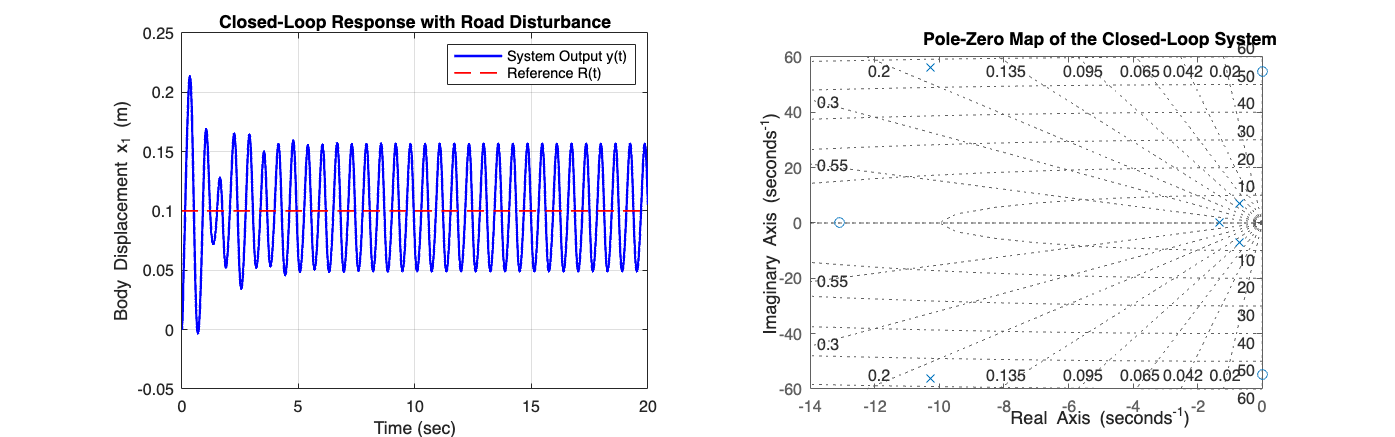

clc; clear; close all;

numG = [1 0 3000]; 
denG = [300 7000 1005000 3000000 45000000]; 
G = tf(numG, denG);

numH = 3000000 * [1 15]; 
denH = denG;
H = tf(numH, denH);

Kp = 1601; 
Ki = 20950;
C = pid(Kp, Ki);

T_ref = feedback(C * G, 1);

T_dist = H / (1 + C * G);

t = 0:0.001:20;
R = 0.1 * ones(size(t)); 

Yr = 0.1 + 0.05*sin(10*t) + 0.02*cos(20*t); %

y_ref = lsim(T_ref, R, t);      
y_dist = lsim(T_dist, Yr, t);    
y_total = y_ref + y_dist;       

figure('Units', 'normalized', 'Position', [0.1 0.1 0.8 0.4], 'Color', 'w');


subplot(1, 2, 1);
plot(t, y_total, 'b', 'LineWidth', 1.5); hold on;
plot(t, R, 'r--', 'LineWidth', 1.2);
grid on;
title('Closed-Loop Response with Road Disturbance');
xlabel('Time (sec)'); ylabel('Body Displacement x_1 (m)');
legend('System Output y(t)', 'Reference R(t)');

subplot(1, 2, 2);
pzmap(T_ref);
grid on;
title('Pole-Zero Map of the Closed-Loop System');

fprintf('--- قطب‌های سیستم حلقه بسته ---\n');

--- قطب‌های سیستم حلقه بسته ---


disp(pole(T_ref));

 -10.2870 +56.0539i
 -10.2870 -56.0539i
  -0.7189 + 6.9490i
  -0.7189 - 6.9490i
  -1.3217 + 0.0000i

